# SIMULATION INPUTS PAGE - LONGITUDINAL

Use this page to input all simulation input related parameters

** NOTE 

This script is divided into many different sections. The grouping is done based on some similarities. 

To run the sections individually (which will save time) click anywhere on the section and then click the 

`Run Section` button.

A section is demarcated by a blue border.

## IMPORTANT INFORMATION REGARDING INPUT

In this release there are 2 inputs (input signals) which the user is expected to create

- Longitudinal Acceleration Input

- Front and Rear Bump Profile Input

The actual input for the half car model (called `HalfCarModel_11_AeroM.m)` is a torque input at the wheels. The target longitudinal acceleration input is converted to a torque input at the wheel and then applied to the model. This then results in an acceleration output. 

Hence, there is a longitudinal acceleration input (target) and output. 

Because, there is no controller in this model, the correlation between the target and output is not that good.This will imporve once a controller is added. 

**NOTE - Throughout the Model the suffix "1" refers to the front end of the car and "2" refers to the rear end of the car

## `LEGEND`

% Comments (in green) can indicate notes or units 
"EDIT FIELD"; % Indicates a user input is expected


`--- INTERNAL ---` = Code below this heading is for internal use only 

`--- USER ---` = Code below this is is for the user to edit. It can also contain plotting commands for data visualization

%%%%%%%%%%%% --- INTERNAL --- CLASS INITIALZATION
simInputs = SimInputs3;

STRUCT Variable - `s`

## `--- USER ---` GENERAL SIMULATION PARAMETERS

% Simulation Start and End Times
simInputs.tStart = 0; % INPUT START TIME [s]
simInputs.tEnd = 22; % INPUT END TIME [s]

% Sampling Rate
simInputs.fs = 100; % INPUT SIGNAL SAMPLING RATE [Hz]

% Creating a Time Vector
simInputs.time = simInputs.tStart:(1/simInputs.fs):simInputs.tEnd;


## `--- USER ---` Velocity

Input of starting velocity 

** Currently this cannot be set to 0

** At the current stage, care must be taken to ensure that the velocity doesn't start at 0 kmph or finish at  0 kmph. Otherwise the solver either fails or becomes extremely stiff

% Starting Vehicle Velocity
simInputs.vx = 1; % [Kmph]

simInputs.vx = simInputs.vx/(3.6);

## `--- USER ---` ACCELERATION INPUT

Longitduinal Acceleration Input Signal Parameters

*Docuementation on how to create impulse,step and ramp signals below*

[Impulse, Step and Ramp Signals](https://nl.mathworks.com/help/signal/gs/impulse-step-and-ramp-functions.html)

*Documentation on creating other types of signals below*

[Sawtooth, Square, Triangular, Rectangular and Gaussian Signals](https://nl.mathworks.com/help/signal/examples/signal-generation-and-visualization.html)

*Documentation on creating random input signals for frequency analysis below*

[Chirp Signal](https://nl.mathworks.com/help/signal/ref/chirp.html)

[Random Input Signals](https://nl.mathworks.com/help/ident/ref/idinput.html#bvjdts6)

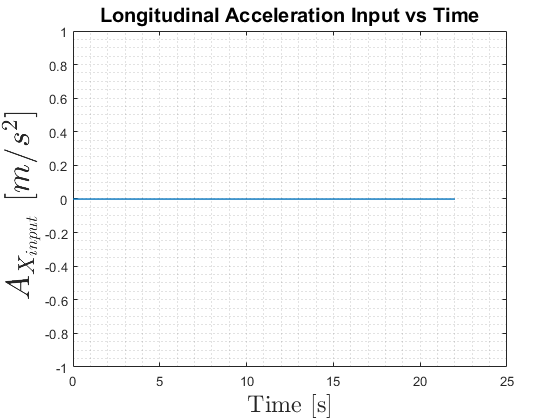

% Longitudinal Acceleration Value
c.ax = 0; % Longitudinal OF ACCELERATION [m/s^2]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% EXAMPLES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% NOTE - Copy & Paste the commands ontp the EDIT FIELD textbox below

% STEP INPUT:  
% simInputs.acc = simInputs.time>= 5;

% CHIRP INPUT: 
% simInputs.acc = chirp(simInputs.time,0.1,simInputs.time(end),10);

% TRIANGULAR PULSE: 
% simInputs.acc = tripuls(simInputs.time-10,5);

% RECTANGULAR PULSE: 
% simInputs.acc = rectpuls(simInputs.time-10,5);

% GAUSSIAN PULSE: 
% [~,~,simInputs.acc] = gauspuls(simInputs.time-10,1,0.15);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% CREATE INPUT SIGNAL
% -> Change code below to change the acceleration input signal
[~,~,simInputs.acc] = gauspuls(simInputs.time-10,1,0.15); % Triangular Pulse Acceleration
simInputs.acc = c.ax*simInputs.acc;
% simInputs.acc(1000:end) = simInputs.acc(1000:end)+1;


% Resultant Force Distribution
simInputs.forceDis = 50;
simInputs.forceDis = simInputs.forceDis/100;

% Display 
plot(simInputs.time,simInputs.acc,"LineWidth",1);
title("Longitudinal Acceleration Input vs Time",'FontSize',15);
ylabel({'$A_{X_{input}}\ [m/s^2]$ '},'Interpreter','latex','FontSize',25);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;

## `--- USER ---` ROAD INPUT

Road Input Signal Parameters

*Docuementation on how to create impulse,step and ramp signals below*

[Impulse, Step and Ramp Signals](https://nl.mathworks.com/help/signal/gs/impulse-step-and-ramp-functions.html)

*Documentation on creating other types of signals below*

[Sawtooth, Square, Triangular, Rectangular and Gaussian Signals](https://nl.mathworks.com/help/signal/examples/signal-generation-and-visualization.html)

*Documentation on creating random input signals for frequency analysis below*

[Chirp Signal](https://nl.mathworks.com/help/signal/ref/chirp.html)

[Random Input Signals](https://nl.mathworks.com/help/matlab/ref/rand.html?searchHighlight=rand&s_tid=doc_srchtitle)

** **IMPORTANT** - Please make sure that the input signal starts with 0. Preferably, the first 500 samples should be 0. 

#### FRONT AXLE

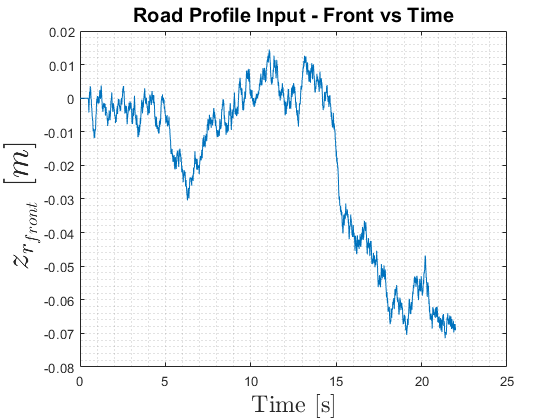

% Road Input Amplitude - Bump Profile Height
c.zr_f = 0.002; % Bump Profile Height [m]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% EXAMPLES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% NOTE - Copy & Paste the commands ontp the EDIT FIELD textbox below

% STEP INPUT:  
% simInputs.zr1 = simInputs.time>= 5;

% CHIRP INPUT: 
% simInputs.zr1 = chirp(simInputs.time,0.1,simInputs.time(end),10);

% TRIANGULAR PULSE: 
% simInputs.zr1 = tripuls(simInputs.time-10,5);

% RECTANGULAR PULSE: 
% simInputs.zr1 = rectpuls(simInputs.time-10,5);

% GAUSSIAN PULSE: 
% [~,~,simInputs.zr1] = gauspuls(simInputs.time-10,1,0.15);

% RANDOM INPUT: 
% simInputs.zr1 = cumsum((2*rand(1,length(simInputs.time))-1));
% simInputs.zr1(1:50) = 0;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% CREATE INPUT SIGNAL
simInputs.zr1 = cumsum((2*rand(1,length(simInputs.time))-1)); % Input Signal Command
simInputs.zr1(1:50) = 0;
simInputs.zr1 = c.zr_f.*simInputs.zr1;


% Compute input signal velocity
simInputs.zr1_d = [0, diff(simInputs.zr1)./diff(simInputs.time)];

% Display 
plot(simInputs.time,simInputs.zr1);
title("Road Profile Input - Front vs Time",'FontSize',15);
ylabel({'$z_{r_{front}}\ [m]$ '},'Interpreter','latex','FontSize',25);
xlabel({'Time [s]'},'Interpreter','latex','FontSize',18);
grid minor;  

#### REAR AXLE

** Currently Front and Rear are treated independently. Update with front inputs going to the rear with a delay to come soon.

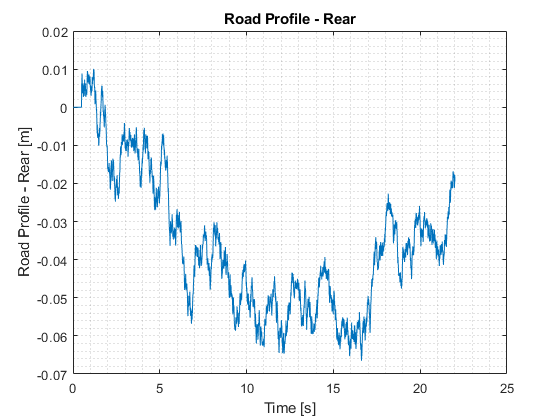

% Rear Road Input Amplitude
c.zr_r = 0.0026; % [m]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% EXAMPLES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% NOTE - Copy & Paste the commands ontp the EDIT FIELD textbox below

% STEP INPUT:  
% simInputs.zr2 = simInputs.time>= 5;

% CHIRP INPUT: 
% simInputs.zr2 = chirp(simInputs.time,0.1,simInputs.time(end),10);

% TRIANGULAR PULSE: 
% simInputs.zr2 = tripuls(simInputs.time-10,5);

% RECTANGULAR PULSE: 
% simInputs.zr2 = rectpuls(simInputs.time-10,5);

%GAUSSIAN PULSE: 
% [~,~,simInputs.zr2] = gauspuls(simInputs.time-10,1,0.15);

% RANDOM INPUT: 
% simInputs.zr2 = cumsum((2*rand(1,length(simInputs.time))-1));
% simInputs.zr2(1:50) = 0;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% CREATE INPUT SIGNAL
simInputs.zr2 = cumsum((2*rand(1,length(simInputs.time))-1)); % Input Signal Commands
simInputs.zr2(1:50) = 0;   
simInputs.zr2 = c.zr_r.*simInputs.zr2;
 

% Compute input signal velocity
simInputs.zr2_d = [0, diff(simInputs.zr2)./diff(simInputs.time)];
    
% Display 
plot(simInputs.time,simInputs.zr2);
xlabel('Time [s]');
ylabel('Road Profile - Rear [m]');
title('Road Profile - Rear');
grid minor;

%%%%%%%%%%%%%%%%%%% --- INTERNAL --- Update Command
%%%%%%%%%%%%%%%%%%%%%%% Safety %%%%%%%%%%%%%%%%%%%%%%%%%%%%
A = exist('hcar','var');

if A == 0
    hcar = HCar;
end
clear A ans;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hcar.simInputs3 = simInputs;
